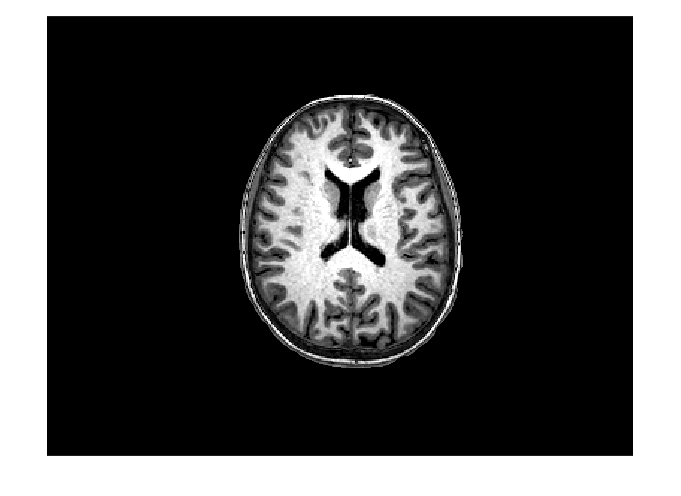

% simple scrip to test the skull segmentation algorithm

% Read an image
img = imread("Images\AX_3.png");
img = imadjust(im2gray(img));


% get background
background = background_seg(img);

% removing background
img(background) = 0;

% storing for comparison
img_original = img;
imshow(img)

%  Top hat transform experimentation
tophat = imbothat(img,strel('disk',10));


% Prelimenary skull stripping?
simplethresh = imbinarize(img);

% Getting part of the skull by connected component analysis
[L,n] = bwlabel(simplethresh);
skull_p1 = L==1;

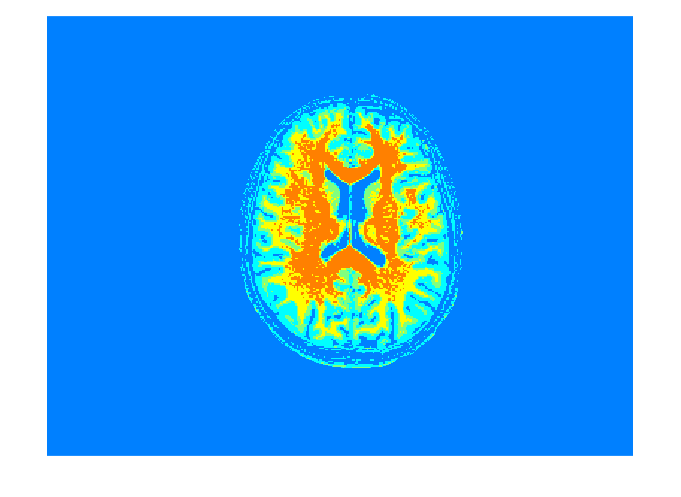


% We want to extract seeds for level set method!!

% stripping (part of) the skull
img(skull_p1) = 0;


% Just basic thresholding
levels = multithresh(img,4);
seg_I = imquantize(img,levels);
seg_RGB = label2rgb(seg_I);
imshow(seg_RGB)

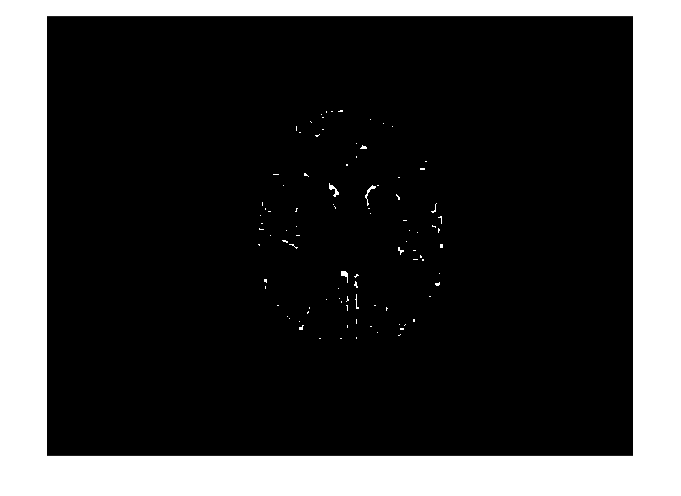


% Getting the seed for white matter levelsets
white_seed = seg_I == 3;
white_seed = imerode(white_seed,strel('disk',5));
imshow(white_seed,[])

white_seed = imcomplement(white_seed);




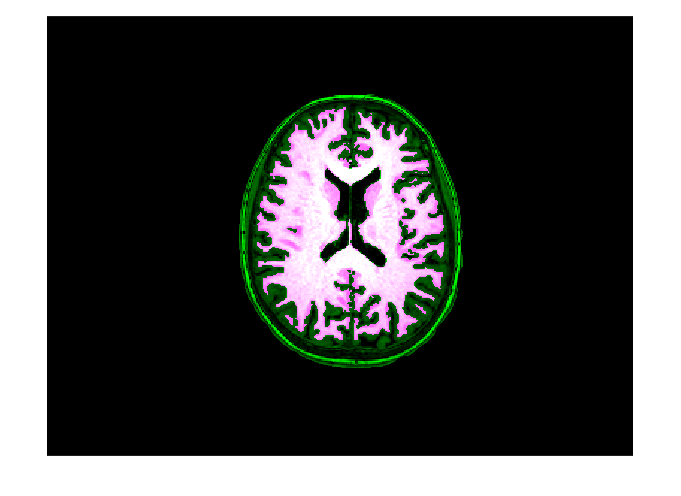

% White matter levelset
img = im2double(img_original);
whitematter = LevelSetSegmentation(img,white_seed,20,200,0);
whitematter = imbinarize(whitematter);


figure
imshowpair(img_original,whitematter)

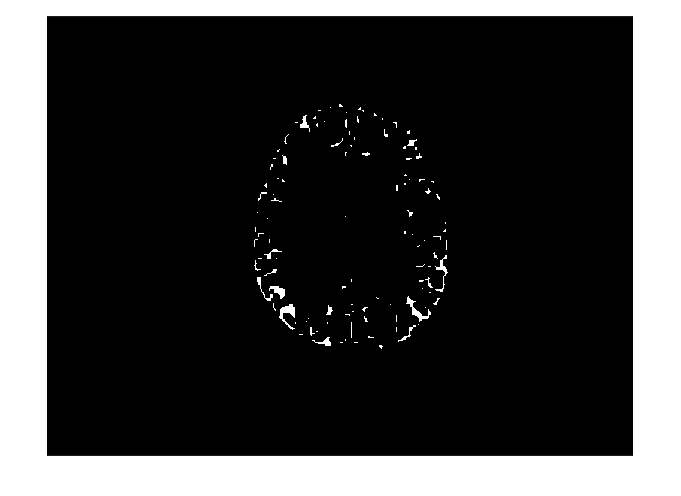

% Grey matter levelset
% Getting the seed 
grey_seed = seg_I == 2;
grey_seed = imopen(grey_seed,strel('disk',4));
grey_seed = imerode(grey_seed,strel("disk",6));
grey_seed(whitematter) = 0;
imshow(grey_seed,[])

grey_seed = imcomplement(grey_seed);


% Grey matter levelset
greymatter = LevelSetSegmentation(img,grey_seed,20,200,0);

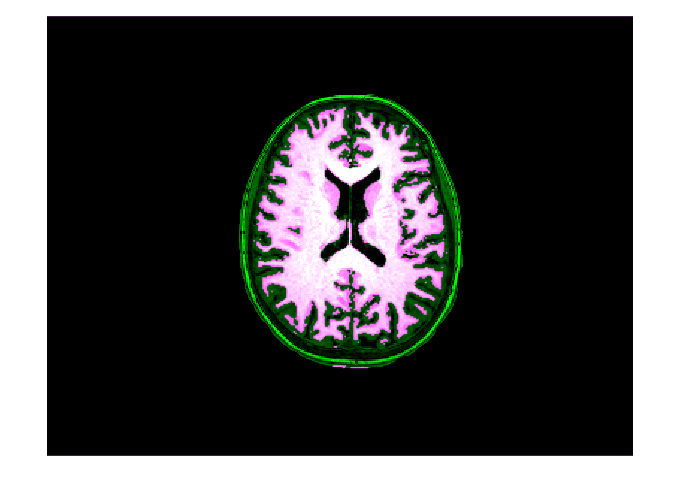

imshowpair(img_original,greymatter)